# **Part 2 of System Identification Exercise List 1**

**Due by October 03, 2026**

**Name:**

**Student ID (I):**

clear all
I=15;% número do aluno

**Question  1  - Probability and statistics**

Brazil has 27 capitals spread across the country's five regions: North, Northeast, South, Southeast, and Center-West. The state capitals are:

**North region**

1- Rio Branco, 2- Macapá, 3- Manaus, 4- Belém, 5- Porto Velho, 6- Boa Vista, 7- Palmas 

**Northeast region**

8- Maceió, 9- Salvador, 10- Fortaleza, 11- São Luís, 12- João Pessoa, 13- Recife, 14- Teresina, 15 Natal

16- Aracaju 

**Central-West Region**

17- Brasília, 18- Goiânia, 19- Cuiabá, 20- Campo Grande 

**Southeast Region**

21- Vitória, 22- Belo Horizonte, 23- Rio de Janeiro, 24 — São Paulo 

**Solth Region**

25- Curitiba, 26- Porto Alegre, 27- Florianópolis 

    Table 1 shows the student ID in the first column and a set of 8 brasilian state capital , listed in

 columns #1, #2, ..., #8.

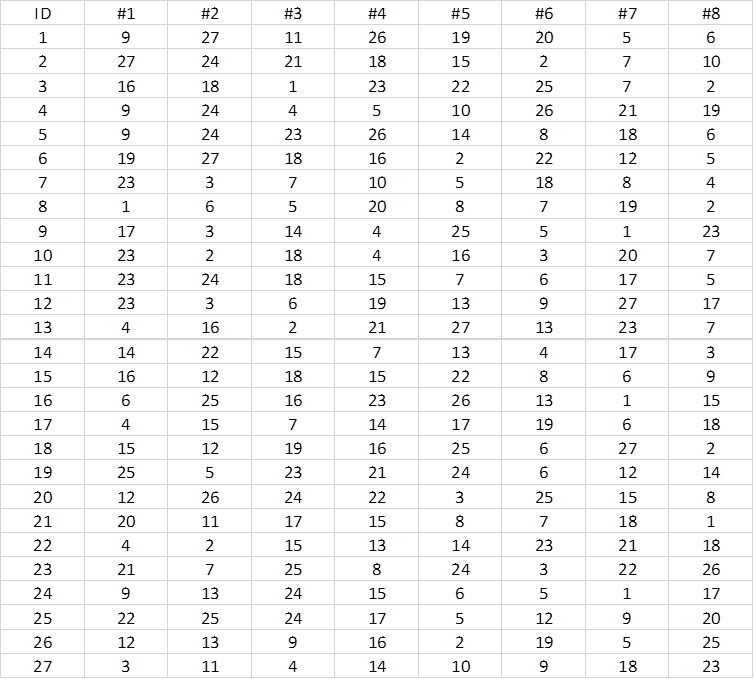

                                 **TABLE 1:Student Id vesus brasilian capitals**

CO2 emission data for Brazilian cities for the 1990, 2000, 2010, 2020, 2021, 2022, 2023, and 2024 are contained in the attached Excel file *"dados-municipais,"* which was extracted from the database at *https://seeg.eco.br/#que*** .**The unit of measurement is years of CO2 (tCO2) per year.

1.1	Using this table, calculate the mean, standard deviation, and histogram of CO2 emissions for all Brazilian cities (population mean) corresponding to the years 1990, 2000, 2010, 2020, 2021, 2022, 2023, and 2024, 

1.2	Based on the results obtained in item 1.1, can we state that the CO2 emission series is strongly stationary?

1.3	For each sample of CO2 emission data from cities #1, #2, ..., #8 (linked to the student ID), obtain the following sample parameters corresponding to the years 1990, 2000, 2010, 2020, 2021, 2022, 2023, and 2024: the mean emission rate and the corresponding confidence interval, the median emission rate, the standard deviation and coefficient of variation, the frequency distribution, the histogram, and the box plot.

1.4	What is the minimum number of cities (samples) required to represent the mean CO2 emission with 98% confidence and an error of less than 10,000.00 tCO2/year?

1.5  Assume that CO₂ emissions from all Brazilian cities in 2024 constitute a random variable X, measured in thousands of tonnes of CO₂. Using the mean and standard deviation calculated in Exercise 1.1, and employing a hypothesis test, determine whether there is evidence that the mean emissions of the 8 cities associated with the student's ID in 2024 differ from the overall mean emissions recorded in 2024.

**Question 2  -  Stochastic processes, time series, and system identification using the autocorrelation function**

The code below generates a stochastic process 

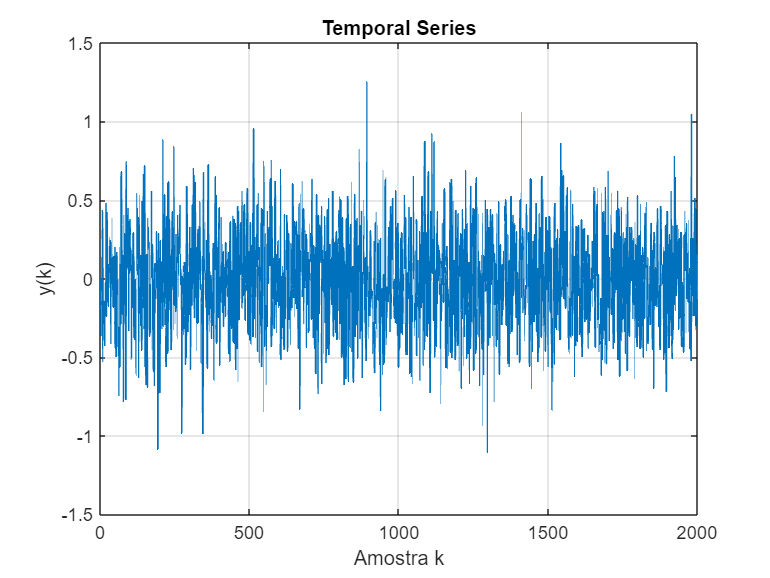

[y]=estocastico(I);
%% Visualizacao
figure;
plot(y, 'LineWidth', 1);
grid on;
xlabel('Amostra k');
ylabel('y(k)');
title('Temporal Series');

2.1 Plot the autocorrelation function.

2.2 Divide this series into 20 blocks of 100 observations. Calculate the mean and standard deviation for the entire series and for each of the 100-observation blocks. What can you say about the stationarity of the series?

2.3 What the order and parameters of the  ARMA model that represents this temporal series?

2.4 Let the ARMA process.

where $a_1=\frac{1}{\sqrt{I_d}}$ and $b_1=\frac{1}{I_d}$  and  $e(k)$ is a white noise process, where $e(k)=1$ with probability p, and

$e(k)=0$ with probability 1-p.

2.4 Write the polynomials AR and MA and verify the conditions for the parameters  $p,b_2~ \mbox{and}~a_2$ must satisfy for this process to be stationary and invertible.

2.5.1 Using the probability theory, and considering that the process is stationary, calculate:

a -$\bar{e}=E[e(k)] ~\mbox{and }~ \bar{y}=E[y(k)]$

b - $\gamma_e(k)=E[(e(t)-\bar{e}) (e(t+k)-\bar{e})] ~\mbox{and }~ \gamma_y(k)=E[(y(t)-\bar{y}) (y(t+k)-\bar{y})]$

2.6  - Consider the dc motor presented in the part one of list I

2.6.1 Using the PRBS signal generated by the code in Question 1 of part one of List I , obtain the motor speed impulse response using the autocorrelation method (see Example 4.2.6, p. 194, from Aguirre's book, 3rd edition). Analyze the following cases:

i) Without measurement noise

ii) Consider that the motor speed is subject to zero-mean Gaussian white noise with a standard deviation equal to $10^{-2}$.

Compare the impulse responses obtained in these two cases with the motor’s actual impulse response. Discuss the differences between the results obtained using the convolution and autocorrelation methods.

2.6.2 Using the PRBS signal generated by the code in Question 1 of part one of List I , obtain the motor speed frequency response  using the autocorrelation method,i.e, using the power spectral density function of the input and output signals (see Example 4.4.1, p. 206, of Aguirre's book, 3rd edition).Analyze the following cases:

i) Without measurement noise

ii) Consider that the motor speed is subject to zero-mean Gaussian white noise with a standard deviation equal to $10^{-2}$.

Compare the frequency responses obtained in these two cases with the motor’s actual frequence response. Discuss the differences between the results obtained using the convolution and autocorrelation methods.